%Choose object detection probability
P_D = 0.9;
%Choose clutter rate
lambda_c = 10;
%Create sensor model
range_c = [-1000 1000;-1000 1000];
sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
%Create ground truth model
nbirths = 1;
K = 100;
initial_state.x = [0; 0; 10; 10];
initial_state.P = eye(4);
ground_truth = modelgen.groundtruth(nbirths,initial_state.x,1,K+1,K);
        
%Create linear motion model
T = 1;
sigma_q = 5;
motion_model = motionmodel.cvmodel(T,sigma_q);
        
%Create linear measurement model
sigma_r = 10;
meas_model = measmodel.cvmeasmodel(sigma_r);

%Generate true object data (noisy or noiseless) and measurement data
ifnoisy = 0;
objectdata = objectdatagen(ground_truth,motion_model,ifnoisy);
measdata = measdatagen(objectdata,sensor_model,meas_model);

%Single object tracker parameter setting
P_G = 0.999;            %gating size in percentage
w_min = 1e-3;           %hypothesis pruning threshold
merging_threshold = 2;  %hypothesis merging threshold
M = 100;                %maximum number of hypotheses kept in Gaussian sum filter
density_class_handle = feval(@GaussianDensity);    %density class handle
tracker = singleobjectracker();
tracker = tracker.initialize(density_class_handle,P_G,meas_model.d,w_min,merging_threshold,M);

%Nearest neighbour filter
nearestNeighborEstimates = nearestNeighbourFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);

%Probabilistic data association filter
probDataAssocEstimates = probDataAssocFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);

%Gaussian sum filter
GaussianSumEstimates = GaussianSumFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);

num_ingate = 1

numHypotheses2 at cycle 1
numHypotheses1 at cycle 2
numHypotheses1 at cycle 3
numHypotheses1 at cycle 4
numHypotheses1 at cycle 5
numHypotheses1 at cycle 6
numHypotheses1 at cycle 7
numHypotheses1 at cycle 8
numHypotheses1 at cycle 9
numHypotheses1 at cycle 10
numHypotheses1 at cycle 11
numHypotheses1 at cycle 12
numHypotheses1 at cycle 13
numHypotheses1 at cycle 14
numHypotheses1 at cycle 15
numHypotheses1 at cycle 16
numHypotheses1 at cycle 17
numHypotheses1 at cycle 18
numHypotheses1 at cycle 19
numHypotheses1 at cycle 20
numHypotheses1 at cycle 21
numHypotheses1 at cycle 22
numHypotheses1 at cycle 23
numHypotheses1 at cycle 24
numHypotheses1 at cycle 25
numHypotheses1 at cycle 26
numHypotheses1 at cycle 27
numHypotheses1 at cycle 28
numHypotheses1 at cycle 29
numHypotheses1 at cycle 30
numHypotheses1 at cycle 31
numHypotheses1 at cycle 32
numHypotheses1 at cycle 33
numHypotheses1 at cycle 34
numHypotheses1 at cycle 35
numHypotheses1 at cycle 36
numHypotheses1 at cycle 37
numHypothe

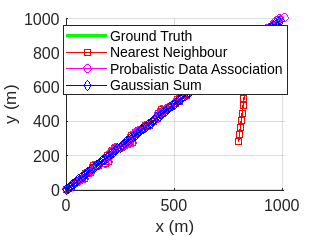


true_state = cell2mat(objectdata.X');
NN_estimated_state = cell2mat(nearestNeighborEstimates');
PDA_estimated_state = cell2mat(probDataAssocEstimates');
GS_estimated_state = cell2mat(GaussianSumEstimates');

figure
hold on
grid on

plot(true_state(1,:), true_state(2,:), 'g','Linewidth', 2)
plot(NN_estimated_state(1,:), NN_estimated_state(2,:), 'r-s' , 'Linewidth', 1)
plot(PDA_estimated_state(1,:), PDA_estimated_state(2,:), 'm-o' , 'Linewidth', 1)
plot(GS_estimated_state(1,:), GS_estimated_state(2,:), 'b-d' , 'Linewidth', 1)

xlabel('x (m)')
ylabel('y (m)')
legend('Ground Truth','Nearest Neighbour', 'Probalistic Data Association', 'Gaussian Sum', 'Location', 'best')

set(gca,'FontSize',12)